## Atomic Force Microscopy

### 1. Importing the force curves

Make a copy of the main.mlx live script and the src directory and paste it to the directory where the force curve files are. The first step assumes that the force curves files are in the same directory as this script. 

This will create the standard directory layout:

`./raw: `Where the jpk-force files are

`./incoming: `Where the relevant channels will be extracted to.

`./processed: `Where the shift-scaled force curves will be safed

And extract  a *filename*_approach.mat and a *filename_*retract.mat matrix, in which the first column is the respective sensor height and the second column the deflection.

Remember to correctly set the path after opening this script.

 
clear;
fullScriptPath = matlab.desktop.editor.getActiveFilename;
[script_dir, ~, ~] = fileparts(fullScriptPath);
% Change directory to the live script's directory
cd(script_dir);
addpath('./src/')

path_incoming = './incoming/';
path_processed = './processed/';
path_raw = './raw/';
if exist(path_incoming,"dir")
     % ─── incoming‐based listing ───
    approachFiles = dir(fullfile(path_incoming, '*_approach.mat'));
    retractFiles  = dir(fullfile(path_incoming, '*_retract.mat'));
    allFiles      = [approachFiles; retractFiles];

    % strip off "_approach.mat" or "_retract.mat" to get base_str
    bases = cellfun(@(nm) regexprep(nm, '_(?:approach|retract)\.mat$', ''), ...
                    {allFiles.name}, ...
                    'UniformOutput', false);
    bases = unique(bases);

    % recreate a struct array named exactly like the old dir() output
    num_curves = numel(bases);
    force_dir = repmat(struct('name',''), num_curves, 1);
    for k = 1:num_curves
        force_dir(k).name = bases{k};
    end
else
    force_dir = dir(fullfile(script_dir,'*.jpk-force'));
end
num_curves=size(force_dir,1)

num_curves = 1008

 
if ~exist(path_incoming,"dir")
    mkdir(path_incoming)
end
if ~exist(path_processed,"dir")
    mkdir(path_processed)
end
if ~exist(path_raw,"dir")
    mkdir(path_raw)
end

force_dir = dir(fullfile(script_dir,'*.jpk-force'));
for i = 1:length(force_dir)
    base_str = force_dir(i).name;
    src_file = fullfile(script_dir, base_str);
    dest_file = fullfile(path_raw, base_str);
    
    try
        copyfile(src_file, dest_file);
        if exist(dest_file, 'file') == 2
            delete(src_file);
        else
            error('File copy failed: %s', base_str);
        end
    catch ME
        fprintf('Error occurred: %s. File was not deleted: %s\n', ME.message, base_str);
    end
end
force_dir = dir(fullfile(path_raw,'*.jpk-force'));
for i = 1:length(force_dir)
    disp(i);
    base_str =force_dir(i).name;
    extract(path_raw,path_incoming,base_str,'head-height','vDeflection');
end


### 2. Rescaling the force curves

The force curves need to be rescaled in order to get physical units. Two linear fits are to be made to achieve this. One for constant compliance and one for the baseline regions. First the respective intervals need to be chosen to get the best fit for all curves. 

Plot a few example force curves to chose the interval where the baseline and constant compliance is linear.

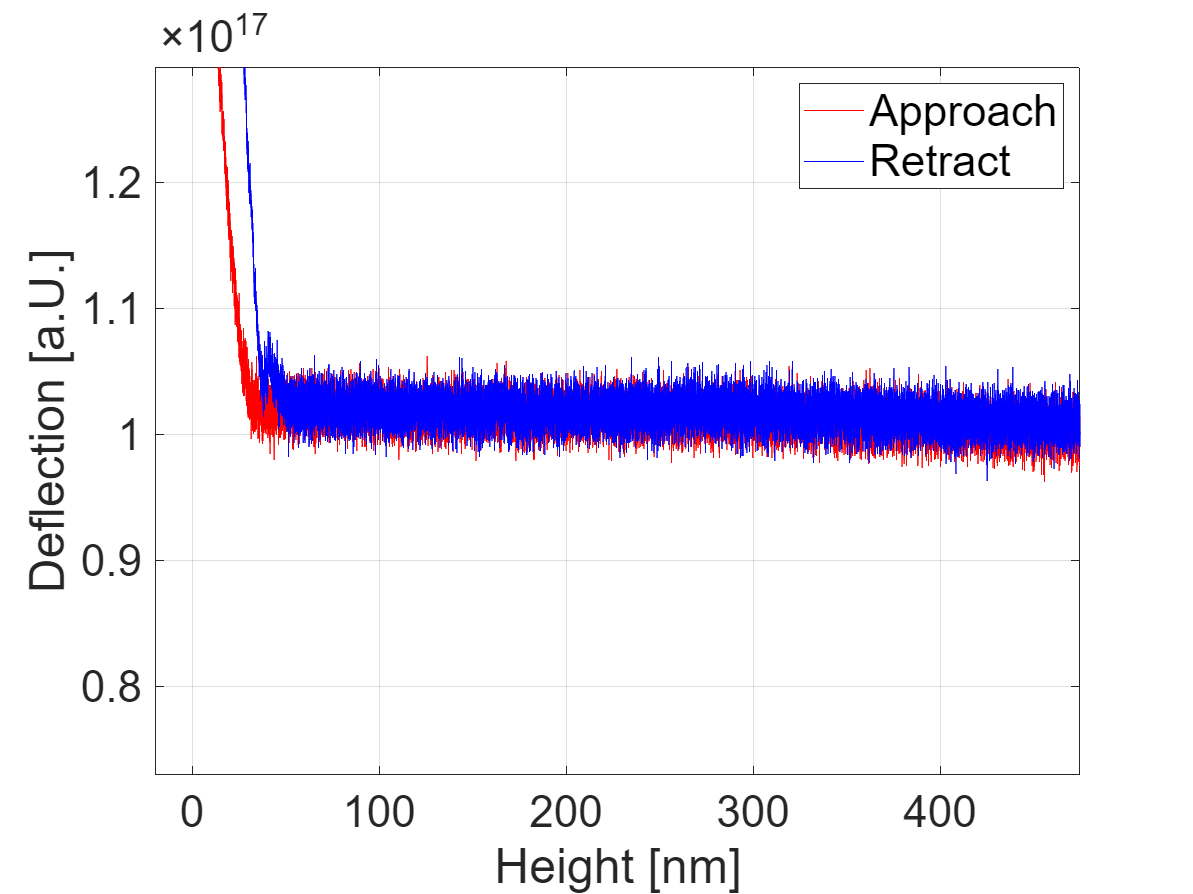

 
cd(script_dir);
curve_id =  178;
base_str = force_dir(curve_id).name;
approach = load(fullfile(path_incoming,[base_str,'_approach.mat']));
retract = load(fullfile(path_incoming,[base_str,'_retract.mat']));

% Plot the approach curve% Create figure with specific size
f = figure('Position', [100, 100, 800, 600]);

% Plot the approach curve
plot(approach.height * 1e9, approach.deflection * 1e9, ...
    'DisplayName', 'Approach', 'Color', 'red');
hold on;

% Plot the retract curve
plot(retract.height * 1e9, retract.deflection * 1e9, ...
    'DisplayName', 'Retract', 'Color', 'blue');

% Add labels
xlabel('Height [nm]', 'FontSize', 22);
ylabel('Deflection [a.U.]', 'FontSize', 22);

% Add a legend with larger font
legend('show', 'FontSize', 22);

% Set axis limits
%xlim([0, 500]);

% Turn on grid
grid on;

% Optional: make appearance more consistent
set(gca, 'FontSize', 22);
box on;

% Optional: set tight layout for export
%set(f, 'PaperPositionMode', 'auto');

% Export to PNG with exact size (800x600 at 100 DPI)
%exportgraphics(f, 'approach_retract_plot.png', 'Resolution', 100);

hold off;

%print(gcf, 'raw_data.png', '-dpng', '-r150');

Then chose the Interval of constant compliance and of the baseline.  The distribution of the Sum of Squared Errors of the fits will be shown. *Should be gaussian and as low as possible?*. 

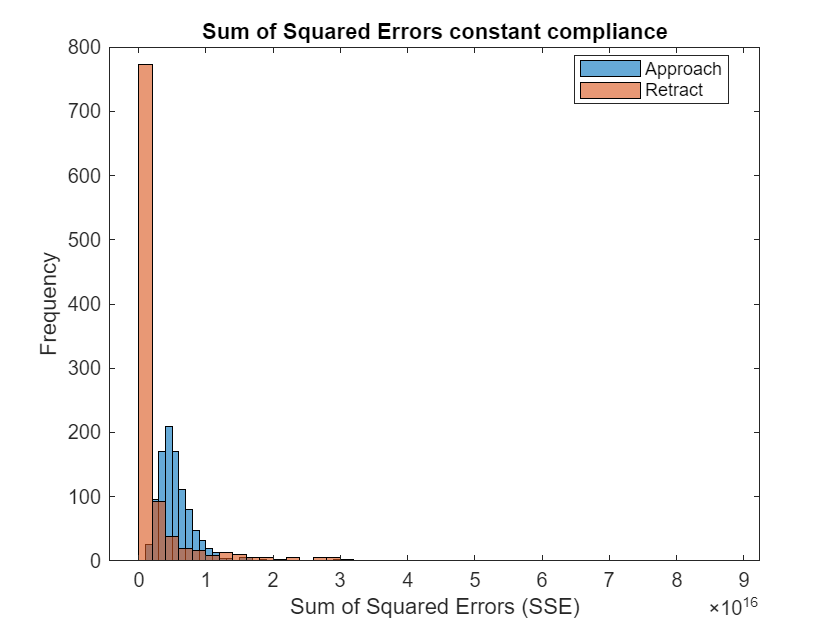

 
cd(script_dir)
const_compliance_min = 0;
const_compliance_max = 1.7e-8;
baseline_min = 2e-7;
baseline_max = 4.5e-7;

n = length(force_dir);
SSEc = zeros(1, n);
mc = zeros(1, n);
bc = zeros(1, n);
SSE = zeros(1, n);
m = zeros(1, n);
b = zeros(1, n);

r_SSEc = zeros(1, n);
r_mc = zeros(1, n);
r_bc = zeros(1, n);
r_SSE = zeros(1, n);
r_m = zeros(1, n);
r_b = zeros(1, n);

for i = 1:length(force_dir)
    base_str = force_dir(i).name;

    % --- Approach curve ---
    [SSEc(i), mc(i), bc(i), SSE(i), m(i), b(i)] = fitforce( ...
        path_incoming, [base_str, '_approach.mat'], ...
        'const_compliance_max', const_compliance_max, ...
        'baseline_min',         baseline_min );

    % --- Retract curve ---
    [r_SSEc(i), r_mc(i), r_bc(i), r_SSE(i), r_m(i), r_b(i)] = fitforce( ...
        path_incoming, [base_str, '_retract.mat'], ...
        'const_compliance_max', const_compliance_max, ...
        'baseline_min',         baseline_min );
end

figure;
histogram(SSEc, 'DisplayName', 'Approach')
hold on; 
histogram(r_SSEc, 'DisplayName', 'Retract')
xlabel('Sum of Squared Errors (SSE)'); 
ylabel('Frequency'); 
title('Sum of Squared Errors constant compliance');
legend('Location', 'best');
hold off;

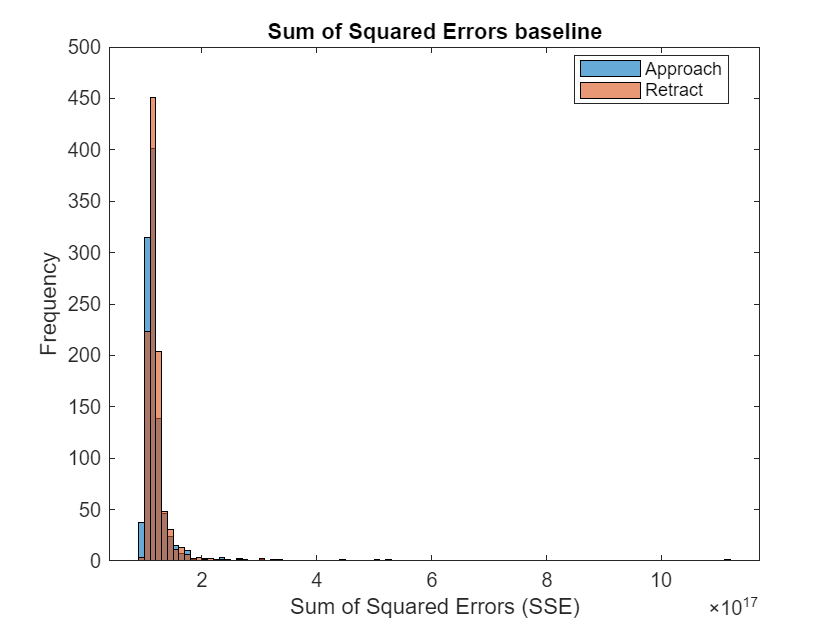


figure;
histogram(SSE,'DisplayName', 'Approach')
hold on;
histogram(r_SSE,'DisplayName', 'Retract');
xlabel('Sum of Squared Errors (SSE)');
ylabel('Frequency'); 
title('Sum of Squared Errors baseline');
legend('Location', 'best');
hold off;

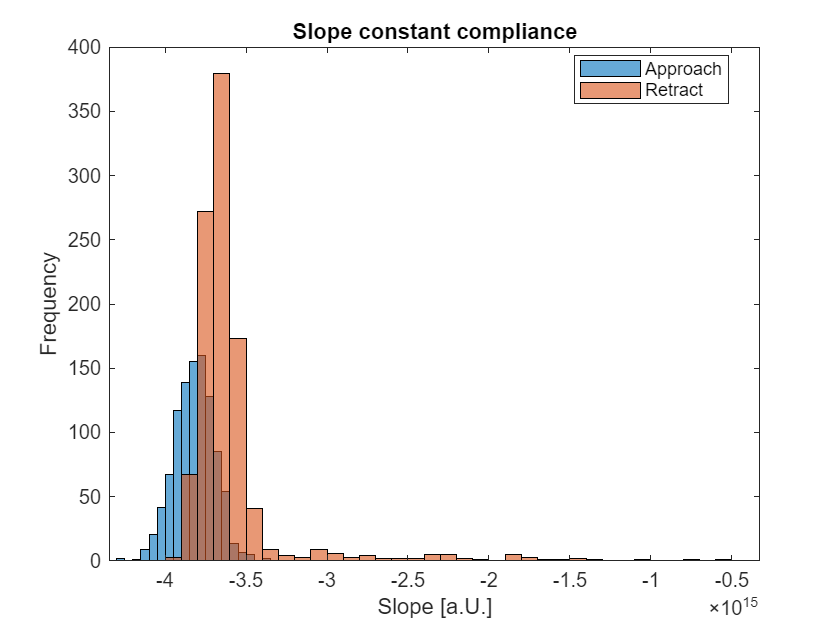

figure;
histogram(mc,'DisplayName', 'Approach')
hold on;
histogram(r_mc,'DisplayName', 'Retract')
xlabel('Slope [a.U.]');
ylabel('Frequency'); 
title('Slope constant compliance');
legend('Location', 'best');
hold off;

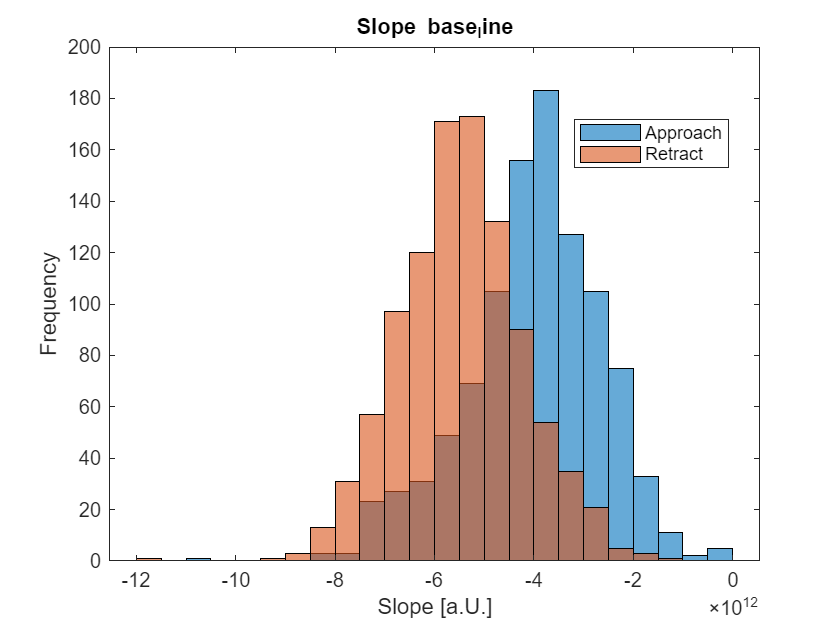

figure;
histogram(m,'DisplayName', 'Approach')
hold on; 
histogram(r_m,'DisplayName', 'Retract')
xlabel('Slope [a.U.]');
ylabel('Frequency'); 
title('Slope base_line');
legend('Location', 'best');
hold off;

You can again inspect the force curves with their fits.

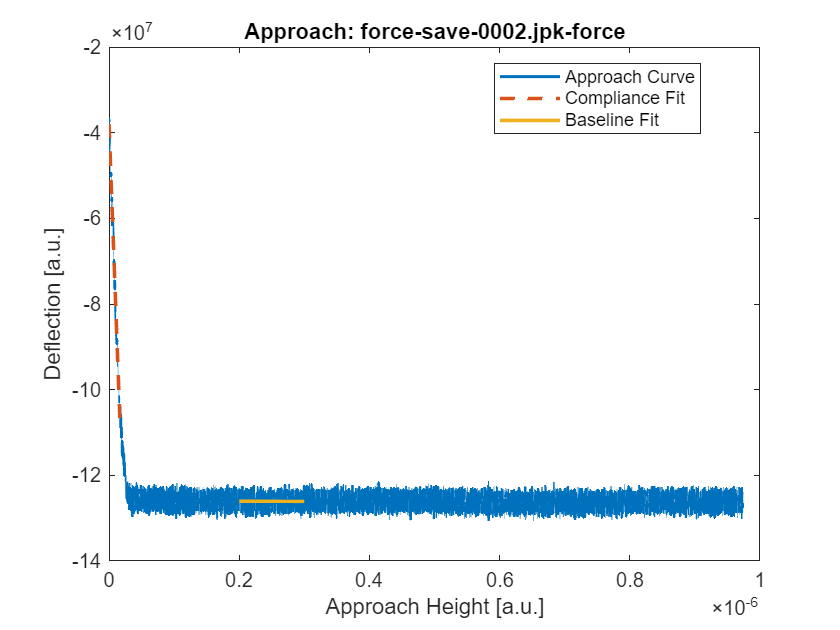

 
cd(script_dir);

curve_id = 3;
base_str = force_dir(curve_id).name;

% Load approach/retract data
approach = load(fullfile(path_incoming, [base_str, '_approach.mat']), 'height', 'deflection');
retract  = load(fullfile(path_incoming, [base_str, '_retract.mat']),  'height', 'deflection');

% ==================== Approach ====================
figure;
hold on;
% Plot raw approach curve (default blue)
plot(approach.height, approach.deflection, 'LineWidth', 1.5);

% Plot fits using MATLAB’s default second color (orange)
set(gca, 'ColorOrderIndex', 2);
xC = linspace(const_compliance_min, const_compliance_max, 100);
yC = mc(curve_id) * xC + bc(curve_id);
plot(xC, yC, '--', 'LineWidth', 1.8);

set(gca, 'ColorOrderIndex', 3);
xB = linspace(baseline_min, baseline_max, 100);
yB = m(curve_id) * xB + b(curve_id);
plot(xB, yB, '-', 'LineWidth', 1.8);

xlabel('Approach Height [a.u.]');
ylabel('Deflection [a.u.]');
title(sprintf('Approach: %s', base_str));
legend({'Approach Curve', 'Compliance Fit', 'Baseline Fit'}, 'Location', 'best');
box on;
hold off;

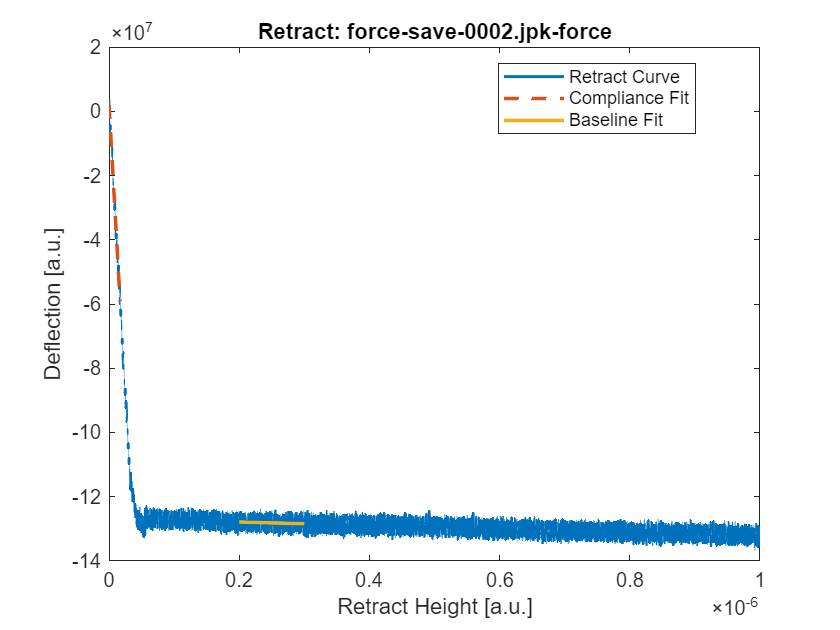


% ==================== Retract ====================
figure;
hold on;
% Plot raw retract curve (default blue)
plot(retract.height, retract.deflection, 'LineWidth', 1.5);

% Plot fits using default orange again
set(gca, 'ColorOrderIndex', 2);
xC_r = linspace(const_compliance_min, const_compliance_max, 100);
yC_r = r_mc(curve_id) * xC_r + r_bc(curve_id);
plot(xC_r, yC_r, '--', 'LineWidth', 1.8);

set(gca, 'ColorOrderIndex', 3);
xB_r = linspace(baseline_min, baseline_max, 100);
yB_r = r_m(curve_id) * xB_r + r_b(curve_id);
plot(xB_r, yB_r, '-', 'LineWidth', 1.8);

xlabel('Retract Height [a.u.]');
ylabel('Deflection [a.u.]');
title(sprintf('Retract: %s', base_str));
legend({'Retract Curve', 'Compliance Fit', 'Baseline Fit'}, 'Location', 'best');
box on;
hold off;

Now the force curves will be rescaled to get physical units. Enter the cantilever spring constant k to get a force on the y axis. POSSIBLY FILTERING HERE.

 
cd(script_dir);
k =0.0000876107;
baseline_min_shifted = zeros(length(force_dir),1);
baseline_max_shifted = zeros(length(force_dir),1);
for i =1:length(force_dir)
    base_str = force_dir(i).name;
    rescale(path_incoming, path_processed, base_str, mc(i),bc(i),m(i),b(i), r_mc(i),r_bc(i),r_m(i),r_b(i),k)
    baseline_min_shifted(i) =baseline_min + (-bc(i)+ b(i))/(mc(i)-m(i));
    baseline_max_shifted(i) =baseline_max + (-bc(i)+ b(i))/(mc(i)-m(i));
end


You can plot a few scaled example curves. 

 
cd(script_dir);
curve_id =  242;
base_str = force_dir(curve_id).name;
approach = load(fullfile(path_processed,[base_str,'_approach_scaled.mat']));
retract = load(fullfile(path_processed,[base_str,'_retract_scaled.mat']));

% Plot the approach curve
plot(approach.shifted_height, approach.scaled_deflection, 'DisplayName', 'Approach Curve');
hold on;
% Plot the retract curve
plot(retract.shifted_height, retract.scaled_deflection, 'DisplayName', 'Retract Curve');
% Add labels
xlabel('Separation [m]');
ylabel('Force [N]');
% Add a legend
legend('show'); % Automatically uses the 'DisplayName' properties of the plots
hold off

### 3. Finding rupture events

If the signal to noise ratio allows, rupture events can be detected and processed automatically. Here we make use of the cantilever "snapping back" after rupture occurs. This usually leads to large positive jumps from negative force values. As noise can also cause similar traces on a per point basis, binning and averaging is necessary to decrease this effect. Finding the correct bin width is the most important pararmeter of this approach, and has to be tuned to the specific pulling velocity. 

First select the rough range in which rupture events are expected and the bin width. (View the docstring of batch_collect_ruptures.m for the other preprocessing parameters.) 

This will then find the largest positive force jump in every smoothed force curve. 

% ----- Heavy preprocessing (run once) -----
 
lower = 1e-8;    % m
upper = 4e-8;    % m
bin_width = 1e-9; %m
out = batch_collect_ruptures(force_dir, path_processed, lower, upper, ...
    'dz_bin', 1e-9, ...
    'use_movmedian', 5, ...
    'strict_window', true);

Picked rupture events in 1008 / 1008 curves.
Largest ΔF = 0.11 pN; Median = 0.01 pN.



%fprintf('Found ruptures in %d / %d curves.\n', nnz(out.idx_curve), numel(out.idx_curve));

Found ruptures in 1008 / 1008 curves.


The force curve are ranked by the magnitude of the force jump as a proxy for how likely it contains a rupture event. You can browse the smoothed force curves and what possible rupture events were found.

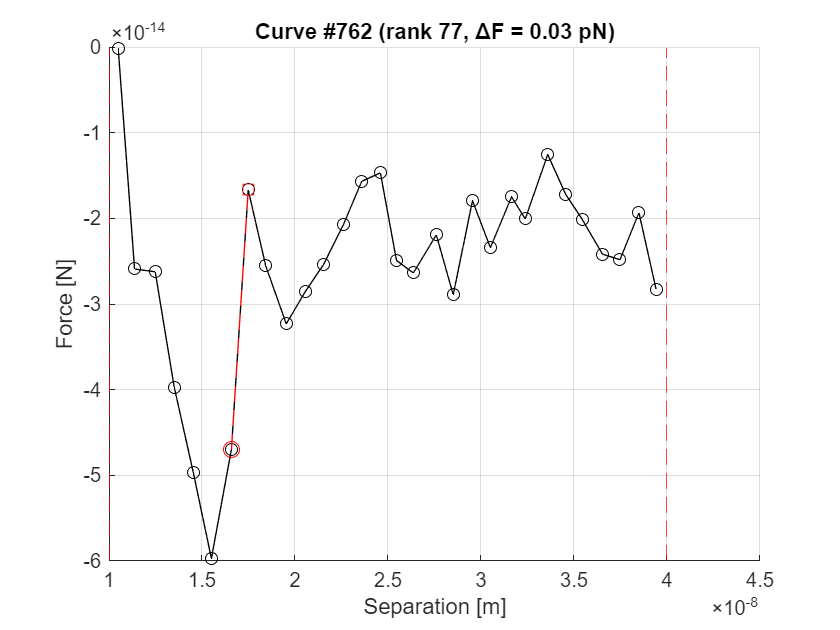

% Browse interactively without recomputing
i =77;
cid = out.sorted_idx(i);
base_str = force_dir(cid).name;

S = load(fullfile(path_processed,[base_str,'_retract_scaled.mat']));
z = S.shifted_height(:); F = S.scaled_deflection(:);
mask = (z <= 1e-7) & isfinite(z) & isfinite(F);
[z_sorted, ord] = sort(z(mask)); F_sorted = F(mask); F_sorted = F_sorted(ord);
F_sorted = movmedian(F_sorted,5);

zmin = max(min(z_sorted), lower); zmax = min(max(z_sorted), upper);
edges = zmin:1e-9:zmax; if edges(end)<zmax, edges(end+1)=zmax; end
b = discretize(z_sorted, edges); nb = max(b(~isnan(b)));
F_bin = nan(nb,1); z_bin = nan(nb,1);
for k = 1:nb
    m = (b == k); if any(m), F_bin(k)=median(F_sorted(m)); z_bin(k)=median(z_sorted(m)); end
end
F_bin = F_bin(isfinite(F_bin)); z_bin = z_bin(isfinite(z_bin));

dF = diff(F_bin); zL = z_bin(1:end-1); zR = z_bin(2:end);
FL = F_bin(1:end-1); FR = F_bin(2:end);
[~,k] = max(dF);  % largest jump
figure(70); clf; hold on; grid on;
plot(z_bin, F_bin,'k-o'); xline(lower,'r--'); xline(upper,'r--');
plot(zL(k),FL(k),'ro','MarkerSize',8); plot(zR(k),FR(k),'rs','MarkerSize',7);
plot([zL(k) zR(k)],[FL(k) FR(k)],'r--');
title(sprintf('Curve #%d (rank %d, ΔF = %.2f pN)', cid, i, dF(k)*1e12));
xlabel('Separation [m]'); ylabel('Force [N]');

num_curves = numel(force_dir);
if ~exist('has_event','var') || numel(has_event) ~= num_curves
    has_event = false(1, num_curves);
end

You can plot the curves and assign whether a curve containts a rupture event. If a curve contains >= 1 rupture event you can select it by pressing switch selection. Pressing switch selection again will then in turn discard the curve. Once all curves with rupture events are selected press "Save Selection" to create a renamed copy of the selected force curves for reproducibility later on. If you wish to reset your selection and delete the renamed copies press "Reset".

 
% Example per-curve toggle by currently viewed curve id "cid"
if has_event(cid)
    disp("DISCARD: No rupture events.");
else
    disp("ACCEPT: >= 1 rupture event.");
end

DISCARD: No rupture events.



% Switch selection for this curve id
if has_event(cid)
    has_event(cid) = false;
    disp("The Curve will now be DISCARDED.");
else
    has_event(cid) = true;
    disp("The curve will now be ACCEPTED.");
end

The Curve will now be DISCARDED.


Usually it is easiest to accept a range of force curves.

 
accept_min = 1;
accept_max =77;
ranks = accept_min:accept_max;
ranks(ranks < 1 | ranks > numel(out.sorted_idx)) = [];   % clamp
curve_ids = out.sorted_idx(ranks);                       % map ranks -> curve ids
has_event(curve_ids) = true;
disp(['The curves with ranks ', num2str(accept_min),'..',num2str(accept_max),' were accepted.'])

The curves with ranks 1..77 were accepted.


 
% --- Copy selected curves (by curve id) ---
cd(script_dir);
sel_ids = find(has_event);  % curve ids
for j = 1:numel(sel_ids)
    cid_j    = sel_ids(j);
    base_str = [force_dir(cid_j).name,'_retract_scaled.mat'];
    new_file = [base_str, '_rupture.mat'];
    copyfile(fullfile(path_processed, base_str), ...
             fullfile(path_processed, new_file));
end
disp("Curves with rupture events were copied.");

Curves with rupture events were copied.


 
cd(script_dir);
choice = questdlg(['Do you really want to reset? ' ...
    'All files with the extension *_rupture.mat in ' path_processed ' will be deleted.'], ...
    'Reset Confirmation', 'Yes', 'No', 'No');

% Process the user's choice.
if strcmp(choice, 'Yes')
    % Find all files that end with '_rupture.mat'
    ruptureFiles = dir(fullfile(path_processed, '*_rupture.mat'));
    has_event = false(1,num_curves);
    % Loop over each file and delete it.
    for k = 1:length(ruptureFiles)
        fileToDelete = fullfile(path_processed, ruptureFiles(k).name);
        delete(fileToDelete);
    end
    disp('Reset complete: All *_rupture.mat files have been deleted.');
else
    disp('Reset cancelled.');
end

Reset complete: All *_rupture.mat files have been deleted.


### 4. Loading rate and rupture Force

Now an elastic model can be fit to the rupture events to extract loading rates and rupture forces. Either use the User Interface to fine tune the model, by specifiying the initial parameters and clicking on the force curve to select the rupture Intervals or try to fit all rupture events at once.

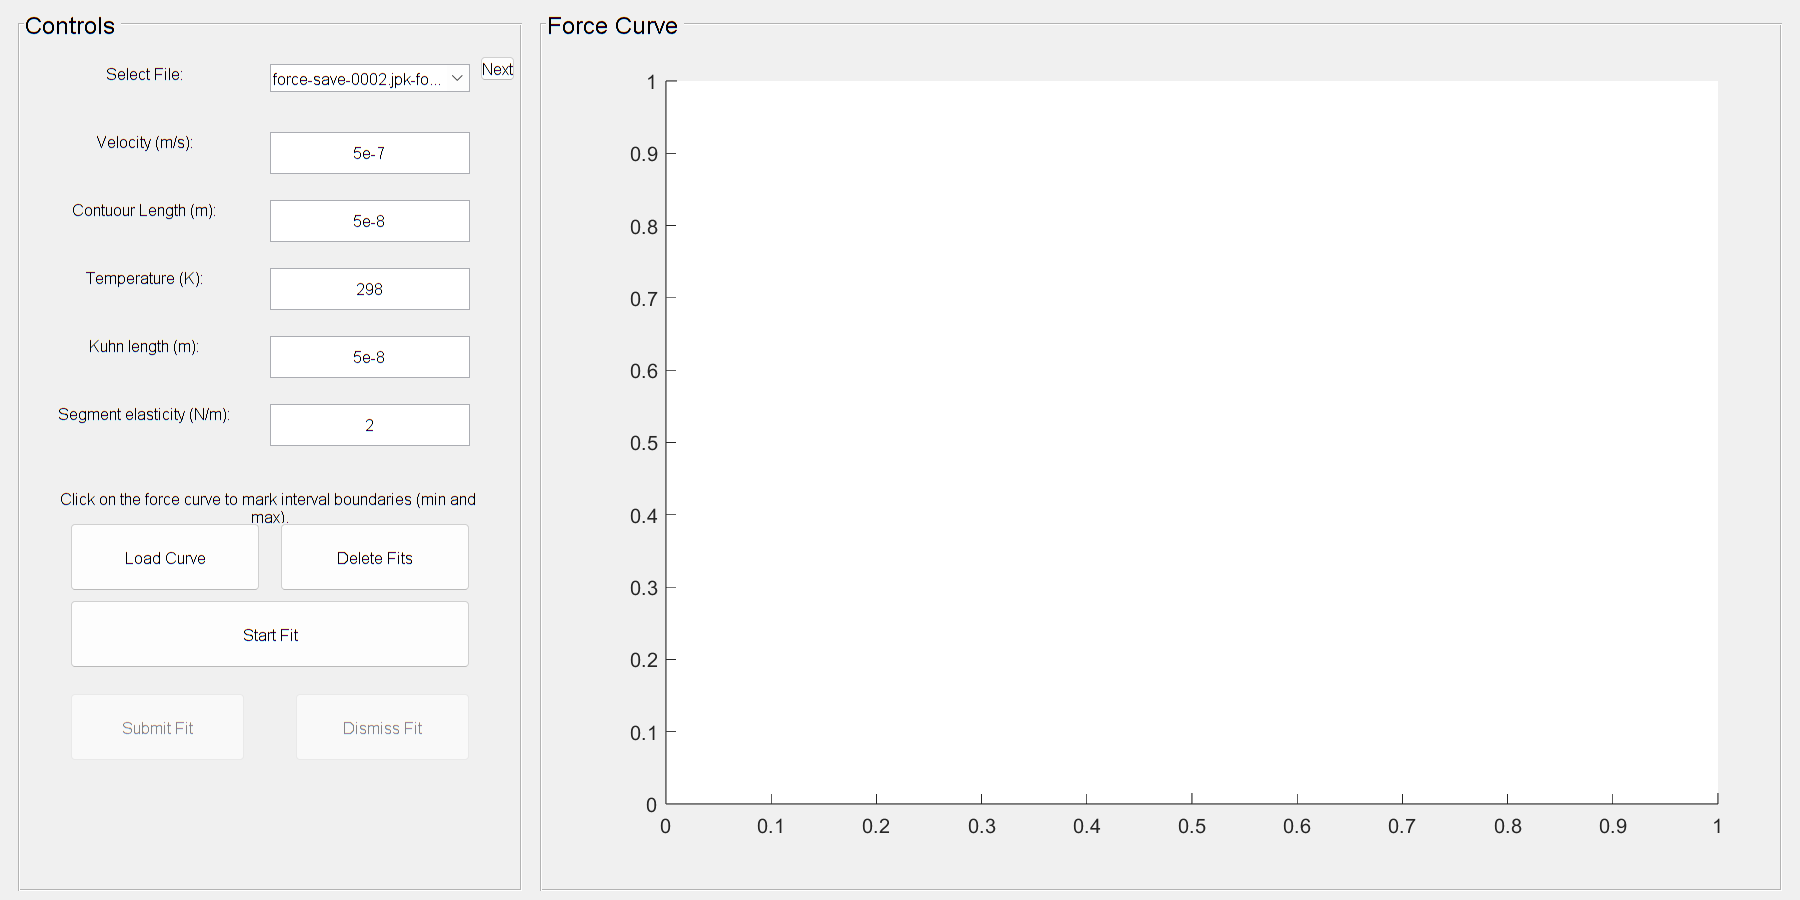

cd(script_dir);
 
fit_mFJC_UI(path_processed);

Plot the rupture force vs the loading rate.

 
cd(script_dir);
fit_results = load(strcat(path_processed,'fitResults.mat')).fitResults;

loading_rate=zeros(1,size(fit_results,1));
unbinding_force=zeros(1,size(fit_results,1));
for i=1:size(fit_results,1)
    loading_rate(i)=-fit_results(i).loading_rate;
    unbinding_force(i)=-fit_results(i).unbinding_force;
end
figure;
scatter(loading_rate*1e12, unbinding_force*1e12,'MarkerEdgeColor', 'b')
grid('on')
set(gca, 'XScale', 'log')
xlabel('loading rate [pN/s]')
ylabel( 'unbinding force [pN]')
% hold off;

Optionally import data from other experiments, by selecting the directory of the other main script. For reproducibility it is recommended to add the paths as actual code.

 
%path = uigetdir();
cd(script_dir);
paths = {
    '/Users/jakob/Desktop/SPG/Slips-SPG/v1000 c250 _ Spot3',
    '/Users/jakob/Desktop/SPG/Slips-SPG/v1000 c250 _ Spot2',
    '/Users/jakob/Desktop/SPG/Slips-SPG/v1000 c250 _2'
};

% Define distinct styles (add more if needed)
colors = {
    [0.0, 0.45, 0.70],  % Blue
    [0.80, 0.47, 0.65], % Reddish purple
    [0.87, 0.56, 0.00]  % Orange-yellow

};
markers = { 's', 'd', '^', 'v', 'p'};
labels = {'Spot 3', 'Spot 2', 'Spot 1'};  % Optional: custom display names

fig = figure('Position', [100, 100, 800, 600]); hold on;
scatter(loading_rate*1e12, unbinding_force*1e12, ...
    'DisplayName', 'Spot 0', ...
    'MarkerFaceColor', 'blue', ...
    'MarkerEdgeColor', 'blue', ...
    'Marker', 'o');

for i = 1:length(paths)
    path = paths{i};
    disp(path)
    
    other = load(fullfile(path, 'processed', 'fitResults.mat')).fitResults;
    
    % Preallocate arrays
    n = numel(other);
    other_loading_rate = zeros(1, n);
    other_unbinding_force = zeros(1, n);
    
    for j = 1:n
        other_loading_rate(j) = -other(j).loading_rate;
        other_unbinding_force(j) = -other(j).unbinding_force;
    end

    % Pick style for this dataset
    c = colors{mod(i-1, length(colors)) + 1};
    m = markers{mod(i-1, length(markers)) + 1};
    lbl = labels{i};  % Or use `sprintf('Dataset %d', i)` if not predefined
    
    scatter(other_loading_rate*1e12, other_unbinding_force*1e12, ...
        'MarkerEdgeColor', c, ...
        'MarkerFaceColor', c, ...
        'DisplayName', lbl, ...
        'Marker', m);
    
    % Aggregate data
    loading_rate = [loading_rate, other_loading_rate];
    unbinding_force = [unbinding_force, other_unbinding_force];
end

% Plot cosmetics
grid on;
set(gca, 'XScale', 'log');
xlabel('loading rate [pN/s]', 'FontSize', 22);
ylabel('unbinding force [pN]', 'FontSize', 22);
legend('show', 'FontSize', 20, 'Location', 'best');
set(gca, 'FontSize', 22);
box on;
hold off;

### Off rate and free energy barrier

Fit a naive multi-bond Bell evans model to nMax populations.

%% --- Setup & Bell–Evans multi‑bond fit ---
% Parameters
 
nMax = 2;                    % # bond populations
kB   = 1.38064852e-23;       % J/K
T    = 293;                  % K

% Raw data (column vectors)
r  = loading_rate(:);        % N/s
F  = unbinding_force(:);     % N

% 1) Initial single‑line fit to seed multi‑pop
X0    = [log(r), ones(size(r))];
beta0 = X0 \ F;
m0    = beta0(1);
xu0   = kB*T / m0;
b1    = beta0(2);

% 2) Intercept shifts & pred curves
b     = b1 + (kB*T/xu0)*log((1:nMax)');
Fpred = m0*log(r) + b';

% 3) Assign each point to nearest n‑curve
[~, grp] = min(abs(Fpred - F), [], 2);

% 4) Final shared‑slope, per‑pop intercept fit
N      = numel(r);
X      = [ log(r), zeros(N,nMax) ];
for n = 1:nMax
    X(grp==n,1+n) = 1;
end
beta  = X \ F;
m     = beta(1);
c     = beta(2:end);
xu    = kB*T / m;
koff0 = (xu/(kB*T)) * exp(-c(1)*xu/(kB*T));

fprintf('Fitted x_u = %.2f nm, k_off^0 = %.2g s^-1\n', xu*1e9, koff0);

%% --- Binning within each subpopulation ---
minElements = 7;
% Preallocate cell arrays to hold per‑pop stats
bin_stats = cell(nMax,1);

for n = 1:nMax
    % extract group data
    idxn   = (grp==n);
    r_n    = r(idxn);
    F_n    = F(idxn);
    
    % sort by rate
    [r_s, I] = sort(r_n);
    F_s      = F_n(I);
    Nn       = numel(r_s);
    nBins    = floor(Nn / minElements);
    
    % allocate
    stats = struct( ...
      'avg_rate',   zeros(nBins,1), ...
      'avg_force',  zeros(nBins,1), ...
      'std_force',  zeros(nBins,1), ...
      'tau',        zeros(nBins,1) );
    
    % loop bins
    for i = 1:nBins
        i0 = (i-1)*minElements + 1;
        i1 = i*minElements;
        rr = r_s(i0:i1);
        ff = F_s(i0:i1);
        
        stats.avg_rate(i)  = mean(rr);
        stats.avg_force(i) = mean(ff);
        stats.std_force(i) = std(ff);
        %stats.tau(i)       = 1 / (koff0 * exp(stats.avg_force(i)*xu/(kB*T)));
        stats.tau(i) = (pi/2.*stats.std_force(i)).^1/2./stats.avg_rate(i);
    end
    
    bin_stats{n} = stats;
end

%% --- Plot: data, fits, and binned stats ---
r_fit = logspace(log10(min(r)), log10(max(r)), 200);

figure('Position',[100,100,900,650]); hold on
colors  = lines(nMax);
markers = {'o','s','^','v','d','p','>','<','h','x'};

% Raw data & fit lines
for n = 1:nMax
    idxn = (grp==n);
    scatter(r(idxn)*1e12, F(idxn)*1e12, 30, ...
        'Marker', markers{n}, ...
        'MarkerFaceColor', colors(n,:), ...
        'MarkerEdgeColor', colors(n,:), ...
        'DisplayName', sprintf('%d‑bond data',n));
    
    Ff = m*log(r_fit) + c(n);
    plot(r_fit*1e12, Ff*1e12, '-', ...
         'Color', colors(n,:), ...
         'LineWidth',1.8, ...
         'DisplayName', sprintf('%d‑bond fit',n));
end
% Binned stats per population
for n = 1:nMax
    stats = bin_stats{n};
    errorbar(stats.avg_rate*1e12, stats.avg_force*1e12, stats.std_force*1e12, ...
        'd', 'MarkerFaceColor', 'black', ...
        'Color', 'black', ...
        'LineWidth',1.2, ...
        'DisplayName', sprintf('%d-bond binned',n));
end

bin_avg_force= bin_stats{1}.avg_force;
tau = bin_stats{1}.tau;
x0 = xu;
set(gca,'XScale','log');
xlabel('Loading rate [pN/s]');
ylabel('Unbinding force [pN]');
legend('Location','northwest');
grid on;
title('Bell–Evans multi‑bond fit + per‑population binned stats');
hold off


Alternatively you can try to fit nMax-gaussians to your nBins. If the number of force curves is high enough this can also identify multiple underlying populations. The naive multi-bond fit is recommended for smaller data sets. 

The first figure show the rupture force distribution in each loading rate bin and the gaussians overlayed. The second figure is the Bell evans model fit to the mean of the gaussians. 

nBins = 5;
nMax = 2;
% Your aggregated data (after data loop)
r = loading_rate(:);          % N/s
F = unbinding_force(:);       % N

% Bin edges in loading‐rate (log‐spaced)
%edges_r = logspace(log10(min(r)), log10(max(r)), nBins+1);
lnr = log(r);
edges_ln = quantile(lnr, linspace(0,1,nBins+1));  
edges_r  = exp(edges_ln);   % back to N/s

figure('Position',[100,100,1000,600]);
for b = 1:nBins
    % select points in this loading‐rate bin
    idx   = r >= edges_r(b) & r < edges_r(b+1);
    Fp    = F(idx)*1e12;      % convert to pN for plotting & fitting
    
    % skip empty bins
    if numel(Fp) < nMax*3
        continue;
    end
    
    % subplot for this bin
    subplot(2, ceil(nBins/2), b);
    
    % histogram of forces, PDF normalization
    h = histogram(Fp, 30, 'Normalization','pdf', ...
        'FaceColor',[0.8 0.8 0.8], 'EdgeColor','none');
    hold on;
    
    % fit 1D GMM to the force data
    gm = fitgmdist(Fp, nMax, ...
        'RegularizationValue',1e-6, ...
        'Options', statset('MaxIter',500));
    
    % overlay the mixture PDF
    x_grid = linspace(min(Fp), max(Fp), 200)';
    pdf_all = pdf(gm, x_grid);
    plot(x_grid, pdf_all, 'r-', 'LineWidth', 1.8, 'DisplayName','GMM PDF');
    
    % (optional) overlay each Gaussian component
    for k = 1:nMax
        comp_pdf = gm.ComponentProportion(k) * ...
                   normpdf(x_grid, gm.mu(k), sqrt(gm.Sigma(:,:,k)));
        plot(x_grid, comp_pdf, '--', 'LineWidth',1.2, ...
             'DisplayName',sprintf('Comp %d',k));
    end
    
    % formatting
    set(gca,'FontSize',10);
    title(sprintf('Bin %d: LR ∈ [%.1g, %.1g] pN/s', b, edges_r(b)*1e12, edges_r(b+1)*1e12));
    xlabel('Unbinding force (pN)');
    ylabel('Probability density');
    %legend('Location','northeast');
    grid on;
end


%% --- Combined Figure: Raw data + binned summary + Bell–Evans fits ---
% PHYSICAL CONSTANTS
kB = 1.38064852e-23;  % J/K
T  = 293;             % K

% YOUR AGGREGATED DATA (after data loop)
r = loading_rate(:);    % N/s
F = unbinding_force(:); % N

% BIN EDGES (log‐spaced in r)
edges_r = logspace(log10(min(r)), log10(max(r)), nBins+1);

% PREALLOCATE SUMMARY ARRAYS
mean_LR = NaN(nBins,1);
mean_F  = NaN(nBins,nMax);
std_F   = NaN(nBins,nMax);

% --- 1) Compute empirical means ± σ per bin & subpopulation via 1D GMM ---
for b = 1:nBins
    idx   = r >= edges_r(b) & r < edges_r(b+1);
    r_bin = r(idx);
    F_bin = F(idx)*1e12;  % convert to pN
    
    if numel(F_bin) < nMax*3
        continue;
    end

    % Fit 1D GMM for this bin
    gm = fitgmdist(F_bin, nMax, ...
          'RegularizationValue',1e-6, ...
          'Options', statset('MaxIter',500));
    C  = cluster(gm, F_bin);   % component assignments

    % Empirical stats for each component
    mu_emp  = zeros(nMax,1);
    sig_emp = zeros(nMax,1);
    for k = 1:nMax
        pts = F_bin(C==k);
        mu_emp(k)  = mean(pts);
        sig_emp(k) = std(pts);
    end

    % Sort so component 1 = lowest‐force, etc.
    [mu_sorted, ord] = sort(mu_emp);
    sig_sorted       = sig_emp(ord);

    % Store
    mean_LR(b)      = mean(r_bin)*1e12;    % pN/s
    mean_F(b,:)     = mu_sorted;           % pN
    std_F(b,:)      = sig_sorted;          % pN
end

% --- 2) Plot raw data in light grey ---
figure('Position',[100,100,800,600]); hold on;
scatter(r*1e12, F*1e12, 8, ...
    'MarkerFaceColor',[0.85 0.85 0.85], ...
    'MarkerEdgeColor','none', ...
    'DisplayName','raw data');

% --- 3) Overlay mean ± σ errorbars ---
colors  = lines(nMax);
markers = {'o','s','^','v','d','p','>','<','h','x'};
for k = 1:nMax
    valid = ~isnan(mean_F(:,k));
    x = mean_LR(valid);         % pN/s
    y = mean_F(valid,k);        % pN
    err = std_F(valid,k);       % pN

    errorbar(x, y, err, ...
        'LineStyle','none', ...
        'Marker', markers{k}, ...
        'Color', colors(k,:), ...
        'MarkerFaceColor', colors(k,:), ...
        'MarkerEdgeColor', colors(k,:), ...
        'LineWidth',1.2, ...
        'DisplayName', sprintf('%d-bond mean \\pm σ', k));
end

% --- 4) Bell–Evans fits on the binned means ---
for k = 1:nMax
    valid = ~isnan(mean_F(:,k));
    r_mean = mean_LR(valid)*1e-12;   % back to N/s
    F_mean = mean_F(valid,k)*1e-12;  % back to N
    sigma  = std_F(valid,k)*1e-12;   % back to N

    x = log(r_mean);
    y = F_mean;
    W = diag(1./(sigma.^2));         % weights

    X = [x, ones(size(x))];          % design matrix
    beta = (X'*W*X)\(X'*W*y);        % weighted least squares

    m = beta(1);
    b = beta(2);
    xu    = kB*T / m;
    koff0 = (xu/(kB*T)) * exp(-b*xu/(kB*T));

    % Plot fit line
    r_fit = logspace(log10(min(r_mean)), log10(max(r_mean)), 200);
    F_fit = m*log(r_fit) + b;
    plot(r_fit*1e12, F_fit*1e12, '-', ...
        'Color', colors(k,:), 'LineWidth',1.8, ...
        'DisplayName', sprintf('%d-bond fit', k));

    % Optional: display parameters
    fprintf('Pop %d: x_u = %.2f nm, k_off^0 = %.2g s^-1\n', ...
        k, xu*1e9, koff0);
end

% --- 5) Final formatting ---
set(gca,'XScale','log');
xlabel('Loading rate (pN/s)');
ylabel('Unbinding force (pN)');
title('Raw data + subpopulation means (\pmσ) + Bell–Evans fits');
legend('Location','northwest');
grid on;
x0 = xu;
k=1;
valid = ~isnan(mean_F(:,k));
%bin_avg_rate = mean_LR(valid)*1e-12;   % back to N/s
%bin_avg_force = mean_F(valid,k)*1e-12;  % back to N
%bin_std_force  = std_F(valid,k)*1e-12; 
%tau = (pi/2.*bin_std_force).^1/2./bin_avg_rate;


Now use Kramers theory to determine the Free Energy Barrier Height. 

tau(F) = tau0(1-v F x0 /dG)^(1-1/v) x exp(-dG(1-[1-v F x0 / dG]^1/v) / kBT) 

Chose how to handle heterogenous subpopulations (either from the multi bond BE fit or GMM) and which subpopulation to use. Enter an initial guess for dG in units of kbT and the shape parameter v. 


 
% --- Choose branch: 'BE' or 'GMM' ---

method = 'BE';   % or 'GMM'
subpop =1;
switch method
    case 'BE'
        st = bin_stats{subpop};  
        bin_avg_rate  = st.avg_rate;
        bin_avg_force = st.avg_force;
        bin_std_force = st.std_force;     
    case 'GMM'
        bin_avg_rate  = mean_LR(valid,subpop)*1e-12;        % back to N/s
        bin_avg_force = mean_F(valid,subpop)*1e-12;       % back to N
        bin_std_force = std_F(valid,subpop)*1e-12;        % back to N
end

% lifetimes from variance (DHS local-normal approx)
tau = (pi/2.*bin_std_force).^1/2./bin_avg_rate;

x0 = xu;   % or recompute if needed

% ─── 2. Constants & dimensionless model ───
v   =0.66;              % shape parameter   
DGhat0 = 10;          % initial guess for dG in thermal energies
kBT = kB * T;            % thermal energy (J)

% p(1)=ΔĜ, p(2)=s0
kramersModel = @(p,F) ...
   p(2) .* ...
   ( max(1 - (v*x0.*F)./(kBT * p(1)), eps) ).^(1 - 1/v) ...
       .* exp( p(1) .* ( ( max(1 - (v*x0.*F)./(kBT * p(1)), eps) ).^(1/v) - 1 ) );



% ─── 3. Data-driven initial guess & bounds ───
%s0_0   = max(tau);      % zero-force lifetime ~ your largest measured τ
s0_0 = 7e-3;

p0 = [ DGhat0, s0_0 ];
%lb = [   0   ,    0  ];
%ub = [  50   ,   10  ];

% ─── 4. Sanity check: is the power‐law base ever ≤0? ───
base_vals = 1 - (v*x0.*bin_avg_force) ./ (kBT * p0(1));
fprintf('Min raw base = %.2e  → clamped to ≥ eps (%.2e)\n', ...
        min(base_vals), eps);
% If min(base_vals)<0, our clamping in the model kicks in and
% guarantees no complex outputs.

% ─── 5. Fit on the log‐scale (stabilizes the exponential) ───
opts = optimoptions('lsqcurvefit','Display','off');

% wrap so we minimize log(tau)−log(model)
fun_log = @(p,F) log( kramersModel(p,F) );
y       = log(tau);

p_fit = lsqcurvefit(fun_log, p0, bin_avg_force, y,[],[], opts);

DGhat_fit = p_fit(1);
s0_fit    = p_fit(2);

fprintf('\n→ Fitted ΔĜ = %.2f kBT\n', DGhat_fit);
fprintf('→ Fitted s0   = %.2e s\n',      s0_fit);

% ─── 6. Plot on semilog‐Y ───
F_plot = linspace(min(bin_avg_force), max(bin_avg_force), 200);
tau_fit = kramersModel(p_fit, F_plot);

figure;
semilogy(bin_avg_force, tau, 'bo','MarkerFaceColor','b');
hold on;
semilogy(F_plot,      tau_fit, 'r-','LineWidth',2);
xlabel('Force F (N)');
ylabel('Lifetime \tau(F) (s)');
legend('data','fit','Location','Best');
grid on;
hold off;
fprintf('Bell-Evans rate = %.2e s^-1\n', koff0);
fprintf('Kramers rate = %.2e s^-1\n', 1/s0_fit);
% Given DGhat_fit, koff0, and s0_fit
nu_BE = koff0     * exp(DGhat_fit);   % from Bell–Evans k_off
nu_K  = (1/s0_fit)* exp(DGhat_fit);   % from Kramers τ0

fprintf('ν_eff (BE) = %.2e s^-1\n', nu_BE);
fprintf('ν_eff (K)  = %.2e s^-1\n', nu_K);

A summary plot of the Bell-Evans and Kramer model.

%% --- Publication‑ready 1‑bond BE figure ---
 
% 1) Dedicated Bell–Evans fit on the 1‑bond population
idx1  = (grp==1);
r1    = r(idx1);
F1    = F(idx1);
X1    = [log(r1), ones(size(r1))];
beta1 = X1 \ F1;
m1    = beta1(1);
b1_1  = beta1(2);

% 2) Prepare figure
f = figure('Position',[100,100,800,600]);
hold on;

% 3) Raw data in light grey
scatter(r*1e12, F*1e12, 20, ...
    'Marker','o', ...
    'MarkerFaceColor',[0.8 0.8 0.8], ...
    'MarkerEdgeColor',[0.8 0.8 0.8], ...
    'HandleVisibility','off');

% 4) 1‑bond BE fit in orange
r_fit = logspace(log10(min(r)), log10(max(r)), 200);
F_BE1 = m1*log(r_fit) + b1_1;
plot(r_fit*1e12, F_BE1*1e12, ...
     'Color',[0.85 0.33 0.10], ...  % MATLAB orange
     'LineWidth',2.5, ...
     'DisplayName','1‑bond Bell–Evans fit');

% 5) 1‑bond binned stats in black
stats1 = bin_stats{1};
errorbar(stats1.avg_rate*1e12, stats1.avg_force*1e12, stats1.std_force*1e12, ...
    's','MarkerSize',8, ...
    'MarkerFaceColor','k', ...
    'MarkerEdgeColor','k', ...
    'LineWidth',1.5, ...
    'DisplayName','1‑bond mean');

% 6) Axes styling
set(gca, ...
    'XScale','log', ...
    'FontSize',22, ...
    'Box','on', ...
    'LineWidth',1.5); 
xlabel('Loading rate [pN/s]','FontSize',22);
ylabel('Unbinding force [pN]','FontSize',22);
grid on;

% 7) Legend
legend('show','Location','southeast','FontSize',22);

% 8) LaTeX annotations at matching font size
tau0_K  = s0_fit;
koff_K  = 1/tau0_K;
koff_BE = koff0;     % from your original BE seed
DG_kBT  = DGhat_fit;

anno = { ...
  sprintf('$k_{\\mathrm{off}}^{\\mathrm{BE}}    = %.2g\\,$s$^{-1}$', koff_BE), ...
  sprintf('$k_{\\mathrm{off}}^{\\mathrm{Kramer}}  = %.2g\\,$s$^{-1}$', koff_K), ...
  sprintf('$x_{u}       = %.2f\\,\\mathrm{nm}$', xu*1e9), ...
  sprintf('$\\Delta G^{\\ddagger} = %.1f\\,k_BT$', DG_kBT)
};
xpos = 10^(log10(min(r*1e12)) + 0.05*(log10(max(r*1e12))-log10(min(r*1e12))));
ypos = 0.95 * max(F*1e12);

%text(xpos, ypos, anno, ...
%     'FontSize',22, ...
%     'Interpreter','latex', ...
%     'VerticalAlignment','top');

hold off;

